# Portfolio Optimization of Power Generation Capacity

Code adapted from *Design Optimization of a Welded Beam, Mathworks.*

## Problem Description

In the initial approach for the problem, we wish to minimize both costs and risks in the design of an optimal portfolio for power generation. We work with two testbeds, PJM and CAISO, markets on opposite coasts of the US with very different current cost and generation profiles. 

As mentioned, there are two objectives: cost and risk. 

Cost (C) will be modeled simply as shown here:


$$C=\sum_{t=1}^N x_t c_t$$


Subscript t refers to the technology, x is the weight of the technology and c is the cost of the technology in $/kw-yr.

Risk (R) is based on variance and is modeled as shown here:


$$R=\sqrt{\sum_i^N \sum_j^N x_i x_j \sigma_i \sigma_j \rho_{\textrm{ij}} }$$


This time i and j both represent the technologies, again x is the weight of the technology, the sigma value is the risk for the technology, and rho represents the correlation between the two technologies. 

The constraints on the problem are non-negativity constraints as well as the need for supply to be equal to demand. Since it is a continuous problem we can ignore the constraint of making supply equal to demand. The sum of the weights must be equal to 1.

The non-negativity constraint is dealt with below by creating bounds. The linear constraints are formulated by creating Aineq and bineq. In this case, the only linear constraint is that the sum of all x values must be equal to 1. 

Note that in this problem we have so far looked at 18 technologies, so that is set here. The sum of VRE, solar PV and onshore wind, is constrained to 0.7.

clear
Number_Techs = 18;
Aeq = ones(1,Number_Techs);
VRE_Const = [1 0 0 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0];
Aineq = VRE_Const;
bineq = [0.7];
beq = [1];

- The bounds on all the variables are that they need to be greater than zero (non-negativity) and less than 1:

lb = zeros(1,Number_Techs);
ub = ones(1,Number_Techs);

## Multiobjective Problem Formulation and `paretosearch` Solution

The problem has been framed in many ways:

- Choose a starting point for costs and find optimal solutions using risk as a single objective (Arnesano et al.) 

- Find bounds close to existing bounds and analyze from there

- Construct a multiobjective problem, showing the variety of feasible solutions.

Here we attempt to solve as a multiobjective problem, which has the advantage of allowing us to understand many possible approaches and to obtain a sense of these solutions without designating a particular starting point. The objective function is introduced here but defined in a separate file. 

fun = @my_obj_fun_CAISO_vector_scaled_levelized;

The `paretosearch` algorithmcan be plotted using `'psplotparetof'. Options are set here. `

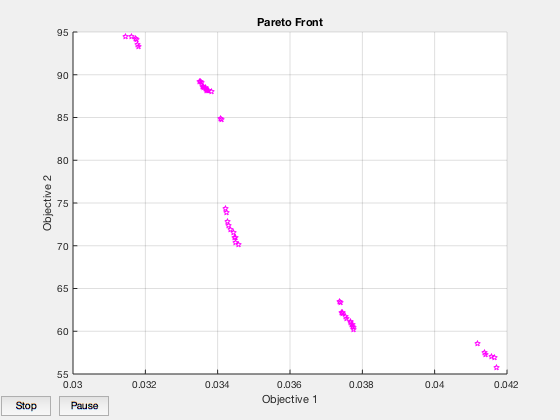

opts_ps = optimoptions('paretosearch','Display','off','PlotFcn','psplotparetof');
rng default % For reproducibility

[x_ps1,fval_ps1,~,psoutput1] = paretosearch(fun,Number_Techs,Aineq, bineq, Aeq,beq,lb,ub,[],opts_ps);

disp("Total Function Count: " + psoutput1.funccount);

Total Function Count: 3045


More points are included so that better solutions and a smoother Pareto front can be found.

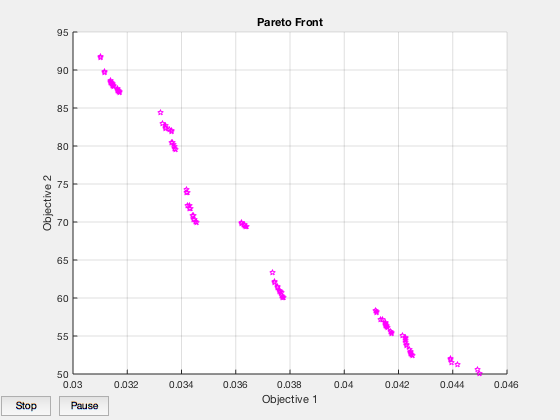

npts = 160; % The default is 60
opts_ps.ParetoSetSize = npts;
[x_ps2,fval_ps2,~,psoutput2] = paretosearch(fun,Number_Techs,Aineq, bineq, Aeq,beq,lb,ub,[],opts_ps);

disp("Total Function Count: " + psoutput2.funccount);

Total Function Count: 11009


## `gamultiobj` Solution

The `gamultiobj` solver is used with equivalent options.  Because the `gamultiobj` solver keeps fewer than half of its solutions on the best Pareto front, use two times as many points as before.

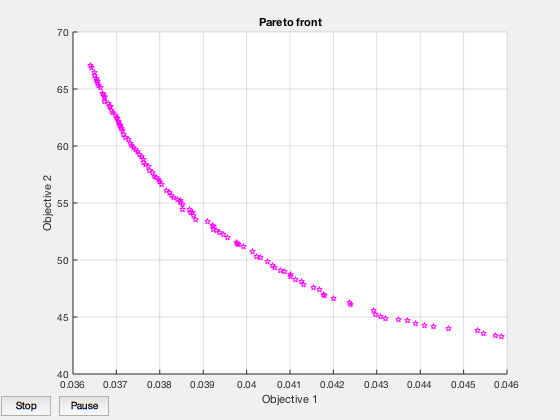

opts_ga = optimoptions('gamultiobj','Display','off','PlotFcn','gaplotpareto','PopulationSize',2*npts);
[x_ga1,fval_ga1,~,gaoutput1] = gamultiobj(fun,18,Aineq, bineq, Aeq,beq,lb,ub,[],opts_ga);

disp("Total Function Count: " + gaoutput1.funccount);

Total Function Count: 48320


`gamultiobj` takes tens of thousands of function evaluations, whereas `paretosearch` takes only thousands.

## Compare Solutions

Both are plotted together here.

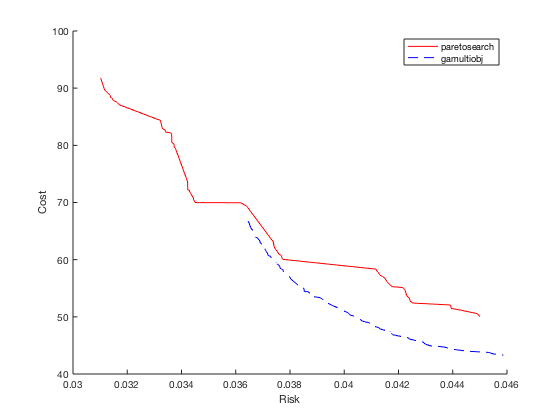

fps2 = sortrows(fval_ps2,1,'ascend');
figure
hold on
plot(fps2(:,1),fps2(:,2),'r-')
fga = sortrows(fval_ga1,1,'ascend');
plot(fga(:,1),fga(:,2),'b--')
%xlim([0.03,0.055])
%ylim([500,7000])
legend('paretosearch','gamultiobj')
xlabel 'Risk'
ylabel 'Cost'
hold off

## Start from Single-Objective Solutions

One idea that is sometimes helpful for finding better solutions using search based solvers is by starting from single-objective solutions. In this case, the single objective solutions will be 100% mixtures of the lowest cost or lowest risk solution, but if we have a more complicated version of the problem, that can change. The `pickindex` function (from MATLAB sample problem) returns the single objective solution from the objective function. Then the solver `fmincon` is used to find the single-objective optima. Here those solutions will be used as the initial starting points for the multiobjective searches in paretosearch and gamultiobj.

x0 = zeros(2,18);
x0f = (lb + ub)/2;
opts_fmc = optimoptions('fmincon','Display','off','MaxFunctionEvaluations',1e4);
x0(1,:) = fmincon(@(x)pickindex(x,1),x0f,Aineq, bineq, Aeq,beq,lb,ub,[],opts_fmc);
x0(2,:) = fmincon(@(x)pickindex(x,2),x0f,Aineq, bineq, Aeq,beq,lb,ub,[],opts_fmc);

Examine the single-objective optima obtained.

my_obj_fun_CAISO_vector_scaled_levelized(x0(1,:))

ans =     0.0253
   98.2116


my_obj_fun_CAISO_vector_scaled_levelized(x0(2,:))

ans =     0.0614
   27.8410


Now we start `paretosearch` from xo, the matrix of the two single-objective solutions. We take out the paretosearch plot function since we want to compare the results with gamultiobj.

opts_ps.InitialPoints = x0;
opts_ps.PlotFcn = [];
[x_psx0,fval_ps1x0,~,psoutput1x0] = paretosearch(fun,Number_Techs,Aineq, bineq, Aeq,beq,lb,ub,[],opts_ps);
disp("Total Function Count: " + psoutput1x0.funccount);

Total Function Count: 9892


We start `ga` from the same initial points, also removing its plot function.

opts_ga.InitialPopulationMatrix = x0;
opts_ga.PlotFcn = [];
[x_gax0,fval_gax0,~,gaoutput] = gamultiobj(fun,18,Aineq, bineq, Aeq,beq,lb,ub,[],opts_ga);
disp("Total Function Count: " + gaoutput.funccount);

Total Function Count: 32960


The solutions are plotted on the same axes.

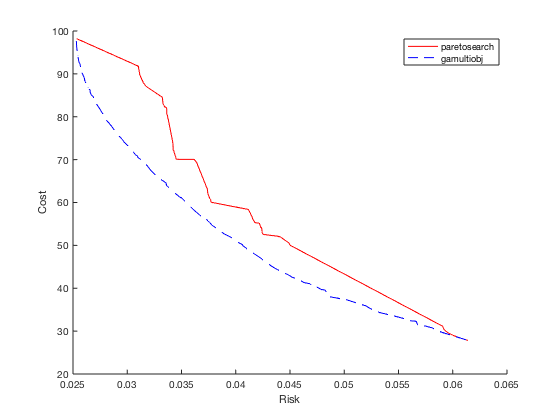

fps = sortrows(fval_ps1x0,1,'ascend');
figure
hold on
plot(fps(:,1),fps(:,2),'r-')
fga = sortrows(fval_gax0,1,'ascend');
plot(fga(:,1),fga(:,2),'b--')
%xlim([0.03,0.055])
%ylim([900,5500])
legend('paretosearch','gamultiobj')
xlabel 'Risk'
ylabel 'Cost'
hold off

## Hybrid Function

`gamultiobj` can call the hybrid function `fgoalattain` automatically to attempt to reach a more accurate solution. 

opts_ga.HybridFcn = 'fgoalattain';
[xgah,fval_gah,~,gaoutputh] = gamultiobj(fun,18,Aineq, bineq, Aeq,beq,lb,ub,[],opts_ga);
disp("Total Function Count: " + gaoutputh.funccount);

Total Function Count: 44794


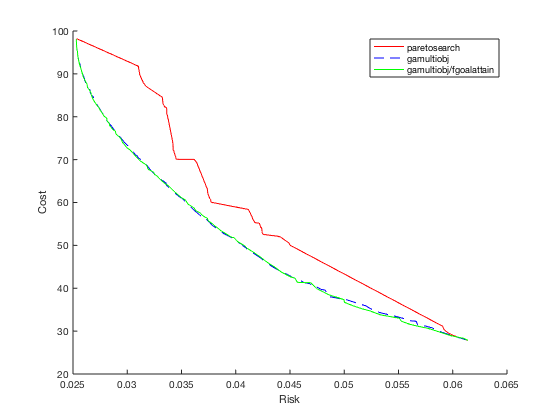

fgah = sortrows(fval_gah,1,'ascend');
figure
hold on
plot(fps(:,1),fps(:,2),'r-')
plot(fga(:,1),fga(:,2),'b--')
plot(fgah(:,1),fgah(:,2),'g-')
%xlim([0.03,0.055])
%ylim([900,5500])
legend('paretosearch','gamultiobj','gamultiobj/fgoalattain')
xlabel 'Risk'
ylabel 'Cost'
hold off

## Run `fgoalattain` Manually from `paretosearch` Solution Points

Although `paretosearch` has no built-in hybrid function, `fgoalattain` can be run from the `paretosearch` solutions. The goal and weights for `fgoalattain` are found by using the same setup for `fgoalattain` as described in [gamultiobj Hybrid Function](docid:gads.bu7fltk-1).

Fmax = max(fval_ps1x0);
nobj = numel(Fmax);
Fmin = min(fval_ps1x0);
w = sum((Fmax - fval_ps1x0)./(1 + Fmax - Fmin),2);
p = w.*((Fmax - fval_ps1x0)./(1 + Fmax - Fmin));
xnew = zeros(size(x_psx0));
nsol = size(xnew,1);
fvalnew = zeros(nsol,nobj);
opts_fg = optimoptions('fgoalattain','Display','off');
nfv = 0;
for ii = 1:nsol
    [xnew(ii,:),fvalnew(ii,:),~,~,output] = fgoalattain(fun,x_psx0(ii,:),fval_ps1x0(ii,:),p(ii,:),...
        Aineq, bineq, Aeq,beq,lb,ub,[],opts_fg);
    nfv = nfv + output.funcCount;
end
disp("fgoalattain Function Count: " + nfv)

fgoalattain Function Count: 40368


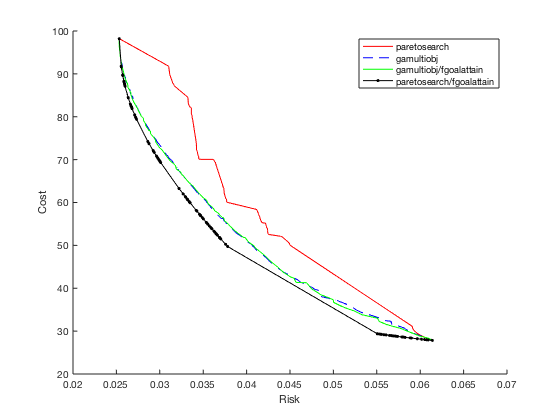

fnew = sortrows(fvalnew,1,'ascend');
figure
hold on
plot(fps(:,1),fps(:,2),'r-')
plot(fga(:,1),fga(:,2),'b--')
plot(fgah(:,1),fgah(:,2),'g-')
plot(fnew(:,1),fnew(:,2),'k.-')
xlim([0.02,0.07])
%ylim([900,4500])
legend('paretosearch','gamultiobj','gamultiobj/fgoalattain','paretosearch/fgoalattain')
xlabel 'Risk'
ylabel 'Cost'

The combination of `paretosearch` and `fgoalattain` creates the most accurate Pareto front. Zoom in to see.

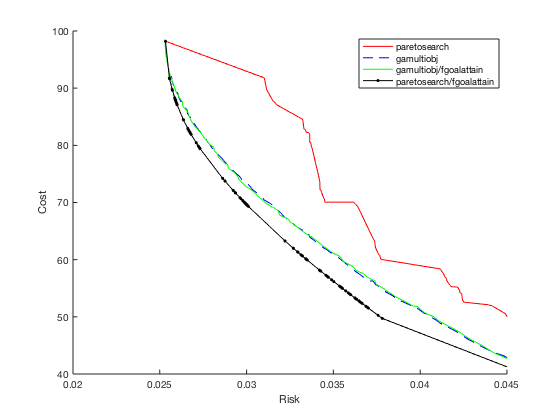

xlim([0.02 0.045])
%ylim([900 4000])
hold off

fprintf("Total function count for gamultiobj alone is %d.\n" + ...
    "For paretosearch and fgoalattain together it is %d.\n",...
    gaoutput.funccount,nfv + psoutput1x0.funccount)

Total function count for gamultiobj alone is 32960.
For paretosearch and fgoalattain together it is 50260.


function z = pickindex(x,k)
    z = my_obj_fun_CAISO_vector_scaled_levelized(x); % evaluate both objectives
    z = z(k); % return objective k
end

## References

Mathworks, 2020. *Design Optimization of a Welded Beam. *[Online] 

Available at: https://www.mathworks.com/help/gads/multiobjective-optimization-welded-beam.html

[Accessed 19 June 2020].